close all
figure(1)
% 绘制末端轨迹
plot(X7(1:70),Y7(1:70))

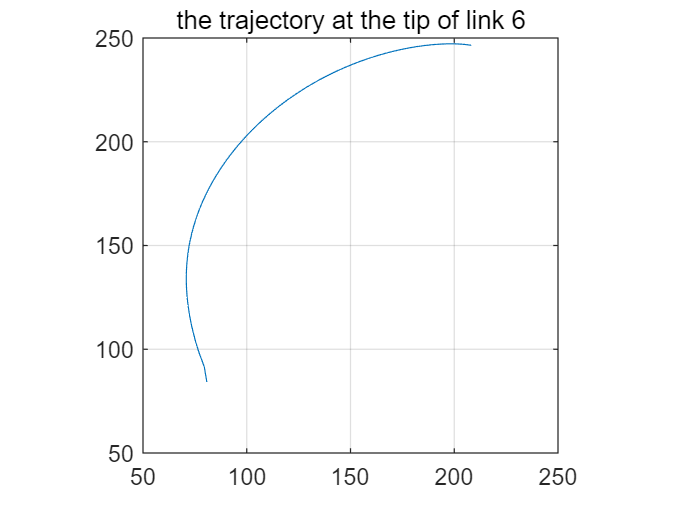

grid on
title('the trajectory at the tip of link 6')
axis equal
xlim([50,250])
ylim([50,250])

%使用前70个值分析
X0c = X0(1:70);
X1c = X1(1:70);
X2c = X2(1:70);
X3c = X3(1:70);
X4c = X4(1:70);
X5c = X5(1:70);
X6c = X6(1:70);
X7c = X7(1:70);
Y0c = Y0(1:70);
Y1c = Y1(1:70);
Y2c = Y2(1:70);
Y3c = Y3(1:70);
Y4c = Y4(1:70);
Y5c = Y5(1:70);
Y6c = Y6(1:70);
Y7c = Y7(1:70);

tx = (pi:-0.02:pi-0.02*68)/pi;
% theta1 对应角度（也可用作时间序列）

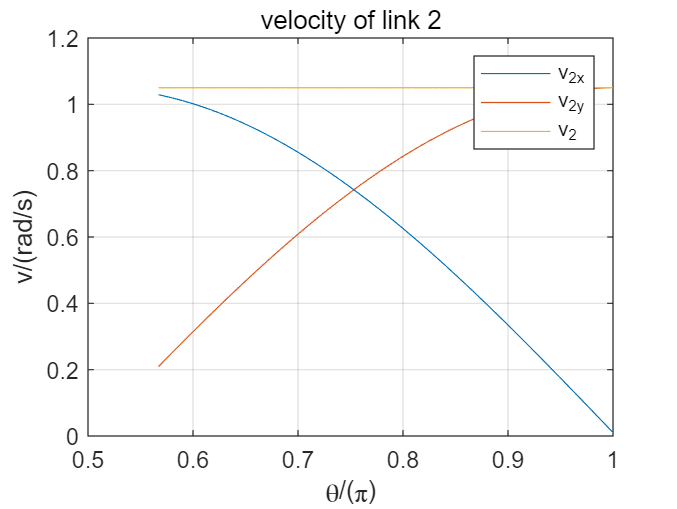

figure(1)
% 位置一阶差分即为速度，下同
vx2 = diff((X2c+X0c)/2);
vy2 = diff((Y2c+Y0c)/2);
v2 = sqrt(vx2.^2+vy2.^2);
plot(tx,vx2)
hold on
plot(tx,vy2)
plot(tx,v2)
grid on
legend('v_{2x}','v_{2y}','v_{2}')
xlabel('\theta/(\pi)')
ylabel('v/(rad/s)')
title('velocity of link 2')

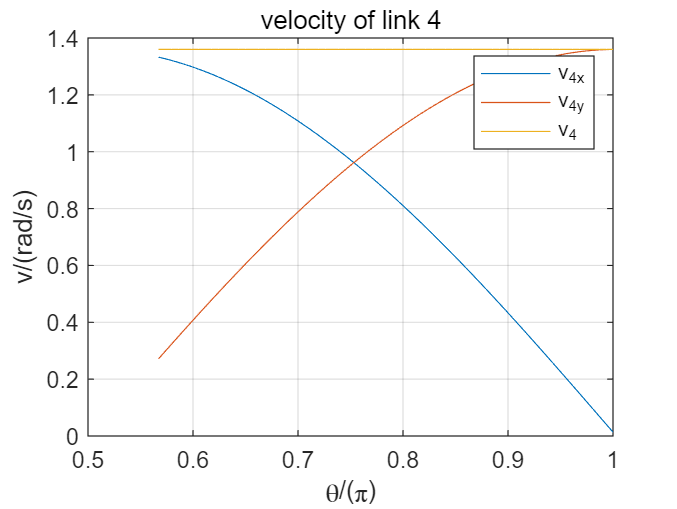

figure(2)
clf
vx4 = diff((X1c+X3c)/2);
vy4 = diff((Y1c+Y3c)/2);
v4 = sqrt(vx4.^2+vy4.^2);
plot(tx,vx4)
hold on
plot(tx,vy4)
plot(tx,v4)
grid on
legend('v_{4x}','v_{4y}','v_{4}')
xlabel('\theta/(\pi)')
ylabel('v/(rad/s)')
title('velocity of link 4')

figure(3)
clf
vx5 = diff((X4c+X5c)/2);
vy5 = diff((Y5c+Y5c)/2);
v5 = sqrt(vx5.^2+vy5.^2);
plot(tx,vx5)

hold on
plot(tx,vy5)

plot(tx,v5)

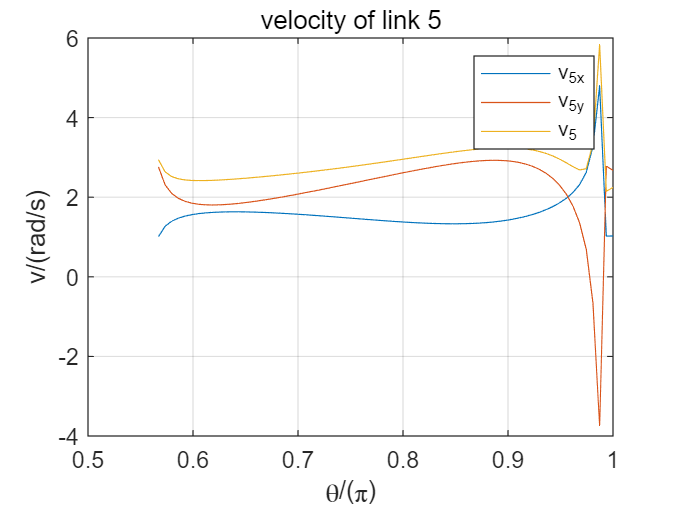

grid on
legend('v_{5x}','v_{5y}','v_{5}')
xlabel('\theta/(\pi)')
ylabel('v/(rad/s)')
title('velocity of link 5')

figure(4)
clf
vx6 = diff((X6c+X5c)/2);
vy6 = diff((Y6c+Y5c)/2);
v6 = sqrt(vx6.^2+vy6.^2);
plot(tx,vx6)

hold on
plot(tx,vy6)

plot(tx,v6)

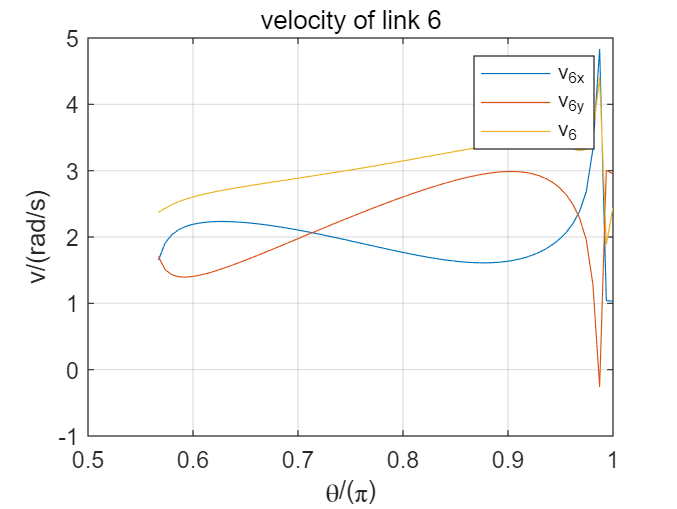

grid on
legend('v_{6x}','v_{6y}','v_{6}')
xlabel('\theta/(\pi)')
ylabel('v/(rad/s)')
title('velocity of link 6')